# Cough Segmentation

remove previous data

close all; clc; clear;

choose gpu

gpuSelected = "1"; % "0" | "1" | "auto"
selectGpu(gpuSelected);

gpu 1


add yamnet to serach path

downloadFolder = fullfile(tempdir,'YAMNetDownload');
loc = websave(downloadFolder,'https://ssd.mathworks.com/supportfiles/audio/yamnet.zip');
YAMNetLocation = tempdir;
unzip(loc,YAMNetLocation);
addpath(fullfile(YAMNetLocation,'yamnet'));

net = yamnet

net =   SeriesNetwork with properties:

         Layers: [86×1 nnet.cnn.layer.Layer]
     InputNames: {'input_1'}
    OutputNames: {'Sound'}


disp(net.Layers);

  86×1 Layer array with layers:

     1   'input_1'                    Image Input              96×64×1 images
     2   'conv2d'                     Convolution              32 3×3×1 convolutions with stride [2  2] and padding 'same'
     3   'b'                          Batch Normalization      Batch normalization with 32 channels
     4   'activation'                 ReLU                     ReLU
     5   'depthwise_conv2d'           Grouped Convolution      32 groups of 1 3×3×1 convolutions with stride [1  1] and padding 'same'
     6   'L11'                        Batch Normalization      Batch normalization with 32 channels
     7   'activation_1'               ReLU                     ReLU
     8   'conv2d_1'                   Convolution              64 1×1×32 convolutions with stride [1  1] and padding 'same'
     9   'L12'                        Batch Normalization      Batch normalization with 64 cha

% analyzeNetwork(net);

Create audioDatastore object of the data and split it into train, validation and test sets

datasetNames = ["voca" "coughvid" "coswara"]; % ["voca" "coughvid" "coswara"]
splitPrcnts = [0.8 0.1 0.1]; % size of train val test in [%]
shuffleDatasets = "no"; % "all" | "trainVal" | "no"

% load data, shuffle and split to train val test
[adsTrain, adsVal, adsTest, adsSpecsTable] = ...
    loadSplitShuffleDatasets(datasetNames, splitPrcnts, shuffleDatasets);
disp(adsSpecsTable);

                             all sets    train    validation    test
                             ________    _____    __________    ____

    No. subjects              "290"      "231"       "30"       "29"
    No. subjects voca         "26"       "20"        "3"        "3" 
    No. subjects coughvid     "145"      "116"       "15"       "14"
    No. subjects coswara      "119"      "95"        "12"       "12"
    No. records               "407"      "325"       "42"       "40"
    No. records voca          "26"       "20"        "3"        "3" 
    No. records coughvid      "145"      "116"       "15"       "14"
    No. records coswara       "236"      "189"       "24"       "23"



Create audioFeatureExtractor object from audio signals

best choices:

window length = 128 [samples]

overlap coefficient between windows = 50 [%]

overlap coefficient between segments = 90 [%]

% win & spectrogram length/overlap info
winInfo.winLen = 128;
winInfo.overlapCoeffWin = 0.5;
winInfo.overlapCoeffSpectrograms = 0.9;

% win & spectrogram normalization info
winInfo.SpectrumType = "magnitude"; % "power" "magnitude"
winInfo.WindowNormalization = false; % true false
winInfo.FilterBankNormalization = "none"; % "area" "bandwidth" "none"

% training options
hyperParameters.MaxEpochs = 15;
hyperParameters.miniBatchSize = 128;
hyperParameters.InitialLearnRate = 0.00001;
hyperParameters.L2Regularization = 0.01;
hyperParameters.LearnRateSchedule = "piecewise"; % "none" "piecewise"
hyperParameters.LearnRateDropPeriod = 1; % 1 2
hyperParameters.LearnRateDropFactor = 0.99;
hyperParameters.ValidationPatience = 6; % positive integer | Inf
hyperParameters.checkpointPath = "checkpoint"; % save net in folder after each epoch

Streamline audio feature extraction (mel-spectrogram)

[afe, winInfo] = setAudioFeatureExtractor(winInfo);

Extract features from train and validation sets

addTrueLbls = "yes";
remLowMagSeg = "yes";

[trainFeatures, trainLabels, trainSpecs] = preprocessSegYamnet(adsTrain, afe, winInfo, addTrueLbls, remLowMagSeg);
[valFeatures, valLabels, valSpecs] = preprocessSegYamnet(adsVal, afe, winInfo, addTrueLbls, remLowMagSeg);

disp(['No. subjects train: ', num2str(numel(trainLabels))]);

No. subjects train: 40388


disp(['No. subjects val: ', num2str(numel(valLabels))]);

No. subjects val: 5464


cough segmentation requires only 2 classes (cough / non-cough).

Read in YAMNet, convert it to a [layerGraph](docid:nnet_ref#mw_399d64ed-680b-46f0-af77-0472ba1910d8), and then replace the final [fullyConnectedLayer](docid:nnet_ref#mw_1e7fbc56-4746-4f30-8cd9-7048ce806a0d) and the final [classificationLayer](docid:nnet_ref#bu5lho8) to reflect the new task.

uniqueLabels = unique(trainLabels);
numClasses = 2;
num_train_pos = sum(trainLabels == "Cough");
num_train_neg = sum(trainLabels == "nonCough");
num_train = num_train_pos + num_train_neg;
classWeightsUniform = 'none';
classWeightsNonUniform = num_train ./ ([num_train_neg num_train_pos] * numClasses);

classWeights = classWeightsNonUniform;

net = yamnet;

lgraph = layerGraph(net.Layers);

newDenseLayer = fullyConnectedLayer(numClasses, "Name", "dense");
lgraph = replaceLayer(lgraph, "dense", newDenseLayer);

newClassificationLayer = classificationLayer( ...
    "Name", "output", ...
    "Classes", uniqueLabels, ...
    'ClassWeights', classWeights);
lgraph = replaceLayer(lgraph, "Sound", newClassificationLayer);

Define training options

validationFrequency = floor(numel(trainLabels)/hyperParameters.miniBatchSize);

options = trainingOptions( ...
    'adam', ...
    'Plots', 'training-progress', ... % 'none' (default) | 'training-progress'
    'Verbose', true, ... % 1 (true) (default) | 0 (false)
    'MaxEpochs', hyperParameters.MaxEpochs, ...
    'MiniBatchSize', hyperParameters.miniBatchSize, ...
    'Shuffle', 'every-epoch', ... % 'once' (default) | 'never' | 'every-epoch'
    'ExecutionEnvironment', 'auto', ... % 'auto' (default) | 'cpu' | 'gpu' | 'multi-gpu' | 'parallel'
    ...
    'ValidationData', {single(valFeatures), valLabels}, ...
    'ValidationFrequency', validationFrequency, ...
    'InitialLearnRate', hyperParameters.InitialLearnRate, ...
    'LearnRateSchedule', hyperParameters.LearnRateSchedule, ... % 'none' (default) | 'piecewise'
    'LearnRateDropPeriod', hyperParameters.LearnRateDropPeriod, ...
    'LearnRateDropFactor', hyperParameters.LearnRateDropFactor, ...
    'L2Regularization', hyperParameters.L2Regularization, ...
    'ValidationPatience', hyperParameters.ValidationPatience, ...
    ...
    'CheckpointPath', hyperParameters.checkpointPath, ...
    'BatchNormalizationStatistics', 'moving' ... % 'population' (default) | 'moving'
    );

Train the network

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |       32.81% |       34.74% |       0.7376 |       0.7813 |      1.0000e-05 |
|       1 |          50 |       00:00:19 |       71.09% |              |       0.5191 |              |      1.0000e-05 |
|       1 |         100 |       00:00:30 |       80.47% |              |       0.4379 |              |      1.0000e-05 |
|       1 |         150 |       00:00:42 |       84.38% |              |       0.2934 |              |      1.0000e-05 |
|       

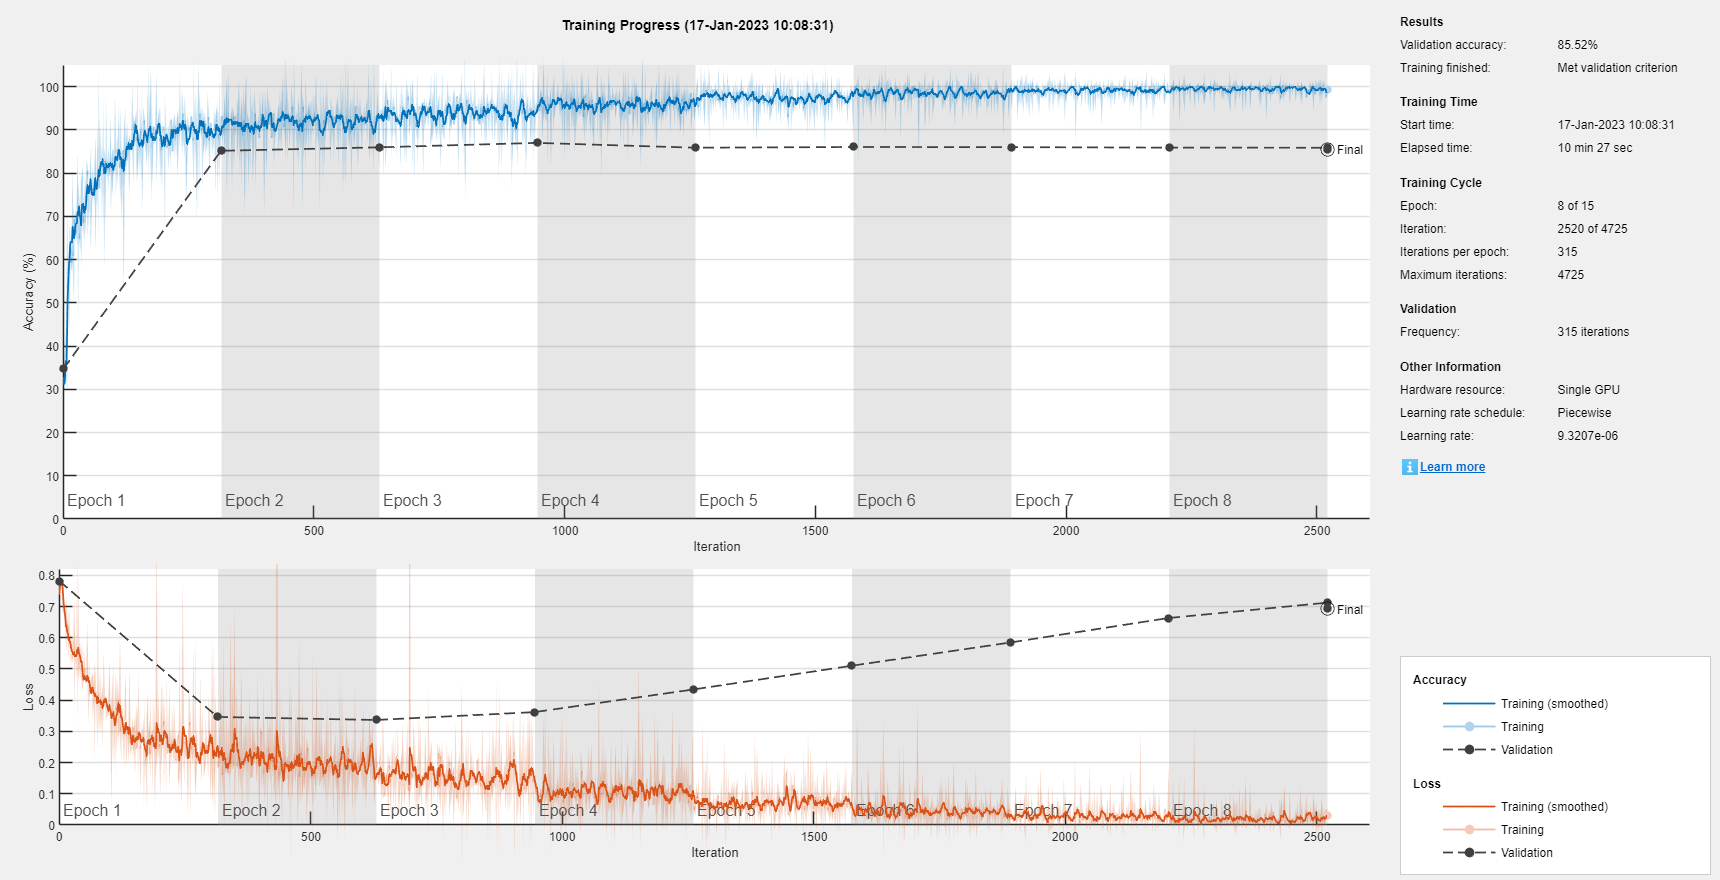

% remove saved nets from previous training
delete(hyperParameters.checkpointPath + "/*");

% train network
[~, netInfo] = trainNetwork(trainFeatures, trainLabels, lgraph, options);

load net (out of all nets yelded from current training) from epoch with best result (lowest validation error)

netSegCoughYamnet = extractNetFromCheckpoint(netInfo, hyperParameters.checkpointPath);

best epoch:
2


% remove saved nets from previous training
delete(hyperParameters.checkpointPath + "/*");

predict on test data (probability for each segment for being part of a cough event)

adsPredict = adsTest;
addTrueLbls = "yes";
[lblsPredDec, lblsTrueDec, adsSpecs] = extractPredictions(netSegCoughYamnet, adsPredict, winInfo, addTrueLbls);

evaluate the performance of the network on the test set using:

- ROC & AUC

- confusion matrix

- accuracy, sensetivity, PPV, F1-score

accuracy = (TP + TN) / (TP + TN + FP + FN)

sensitivity = TP / (TP + FN)

PPV = TP / (TP + FP)

F1-score = 2 * (PPV * sensitivity) / (PPV + sensitivity)

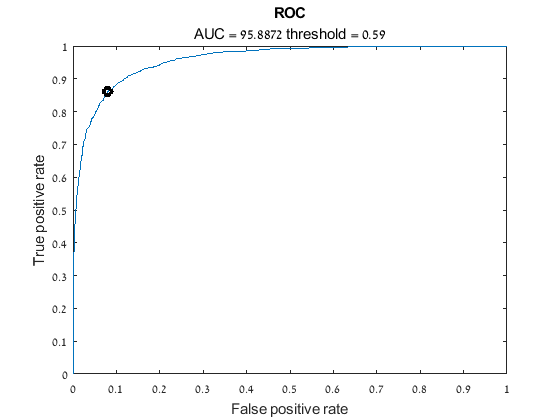

% rocThreshold = 0.5; % choose threshold for ROC curve
plotRoc = "yes";
plotConfMat = "yes";
rocThreshold = findBestThresholdAndPlotROC(lblsPredDec, lblsTrueDec, plotRoc);

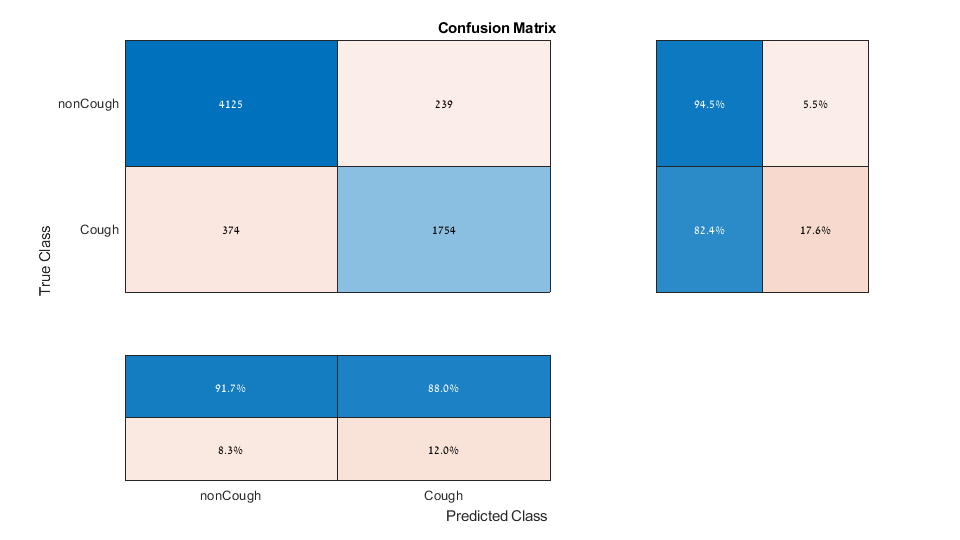

scoresCoughDetectYamnet = extractScoresCoughDetectYamnet(lblsPredDec, lblsTrueDec, rocThreshold, plotConfMat);

disp(scoresCoughDetectYamnet);

                          accuracy [%]    uar [%]    F1 [%]    Sensitivity [%]    ppv [%]    specificity [%]    auc [%]
                          ____________    _______    ______    _______________    _______    _______________    _______

    segment                  90.558       88.474     85.125        82.425         88.008         94.523         95.887 
    event: 50% overlap          NaN          NaN     90.132        90.132         90.132            NaN            NaN 
    event: 70% overlap          NaN          NaN     79.856        77.622         82.222            NaN            NaN 



Save the trained network

% save netSegCoughYamnet.mat netSegCoughYamnet rocThreshold winInfo hyperParameters

plot segmentation results

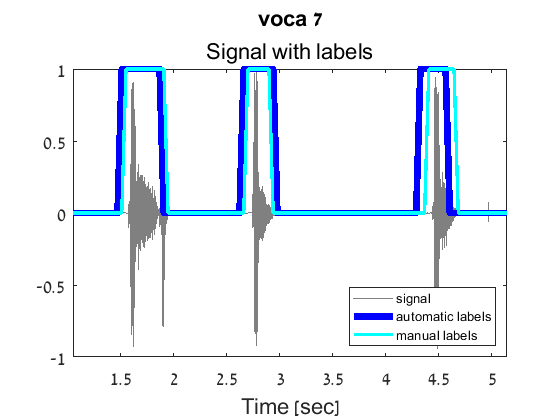

     1



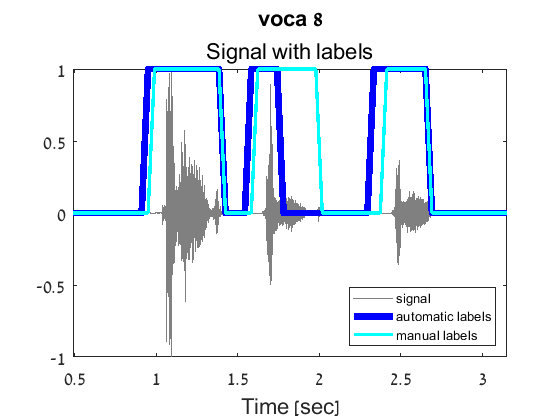

     2



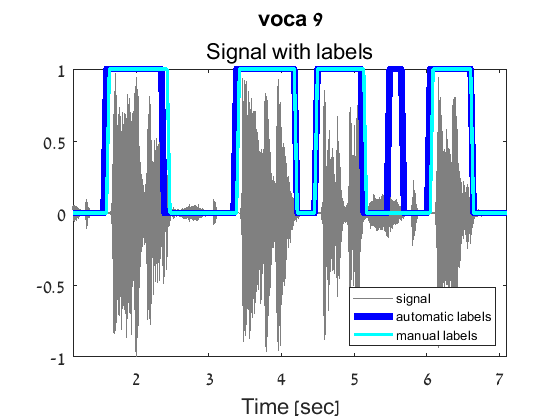

     3



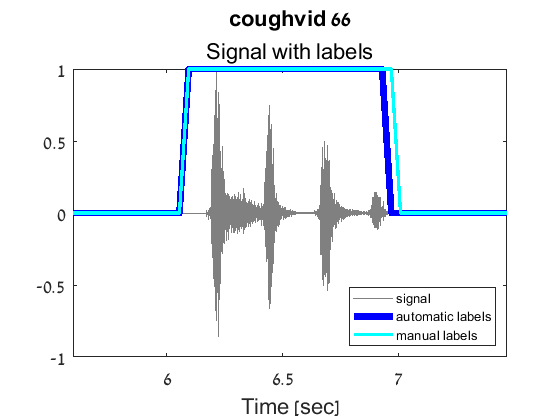

     4



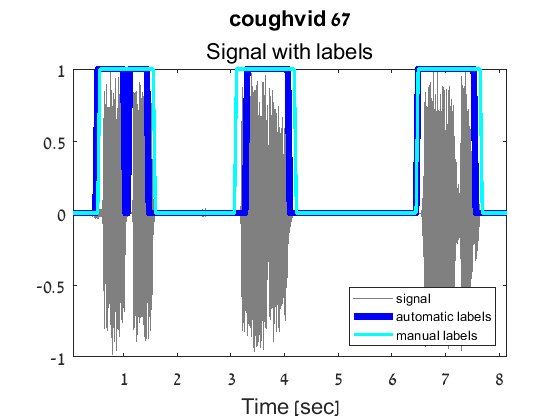

     5



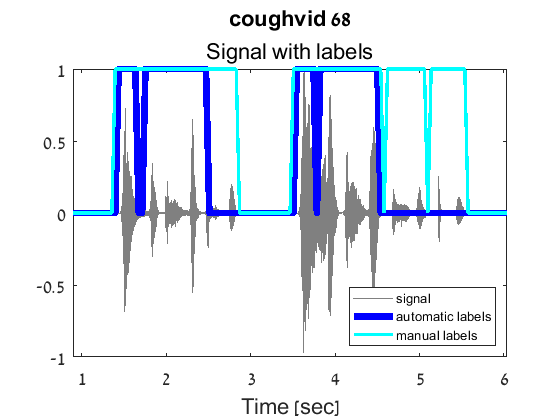

     6



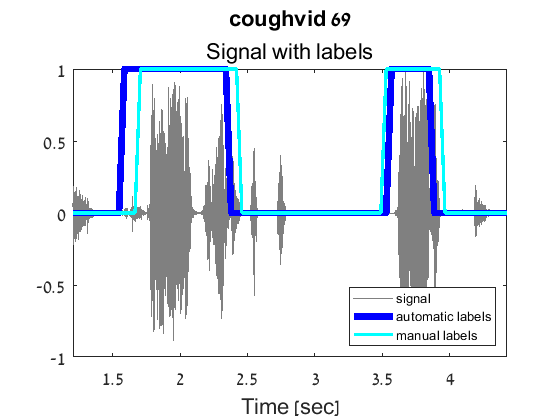

     7



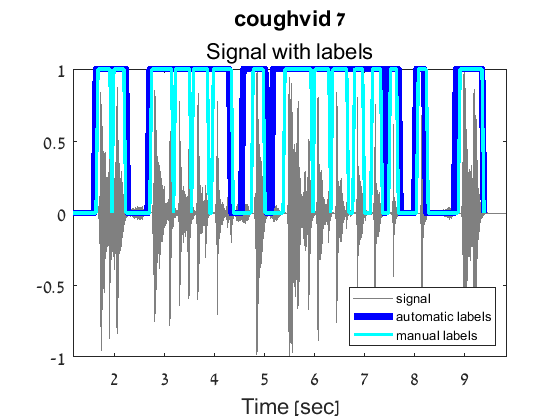

     8



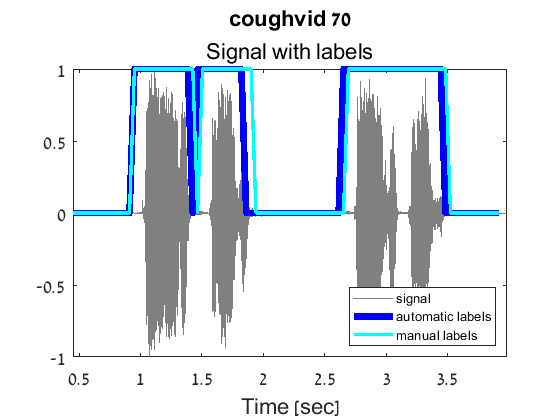

     9



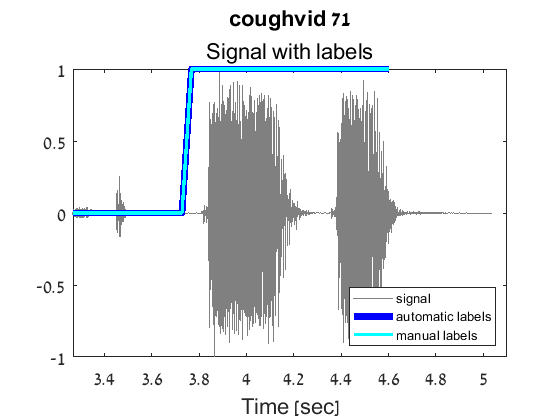

    10



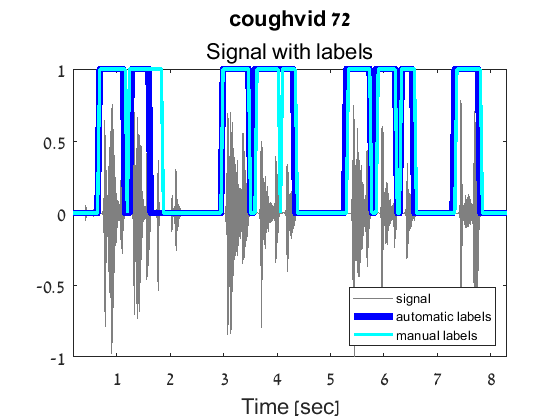

    11



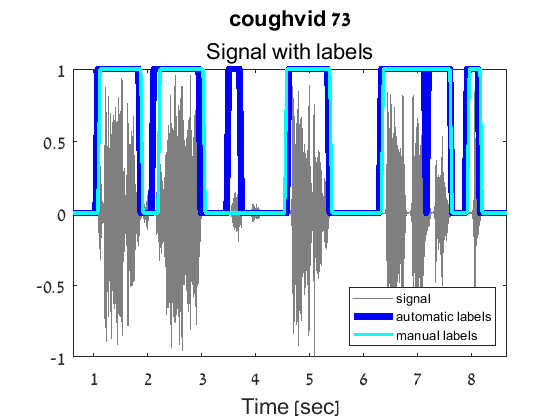

    12



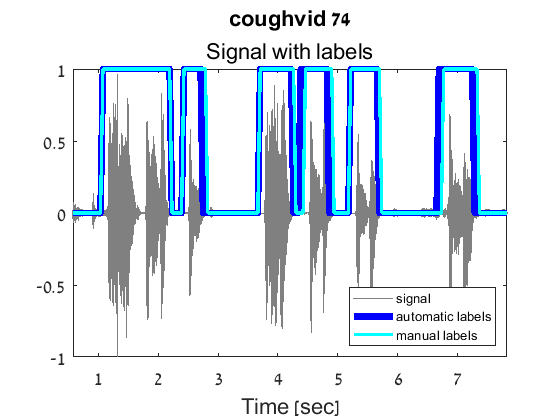

    13



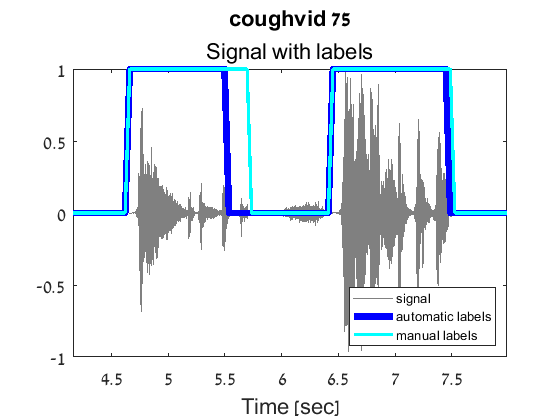

    14



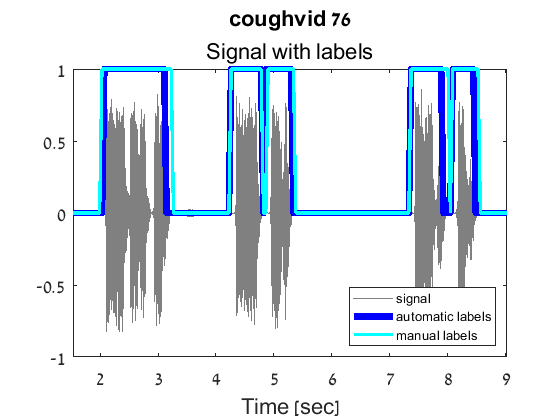

    15



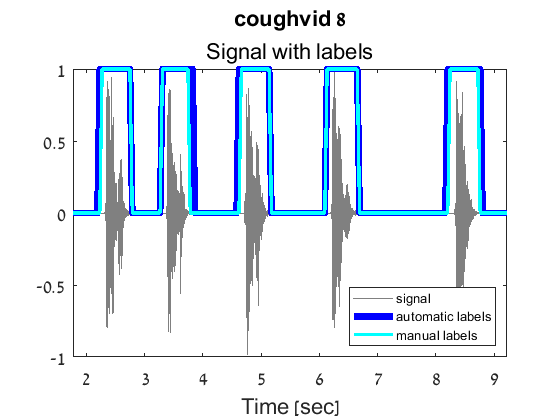

    16



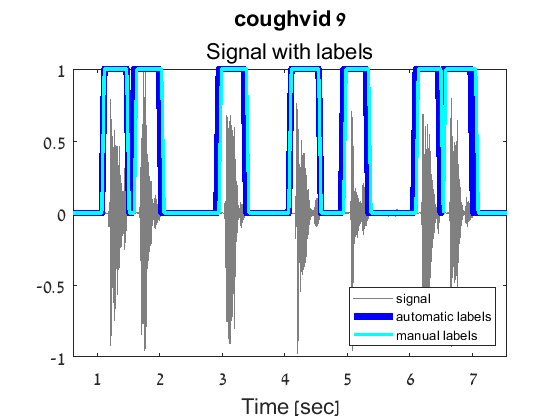

    17



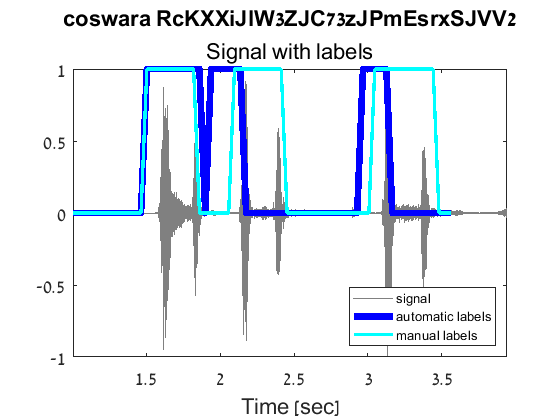

    18



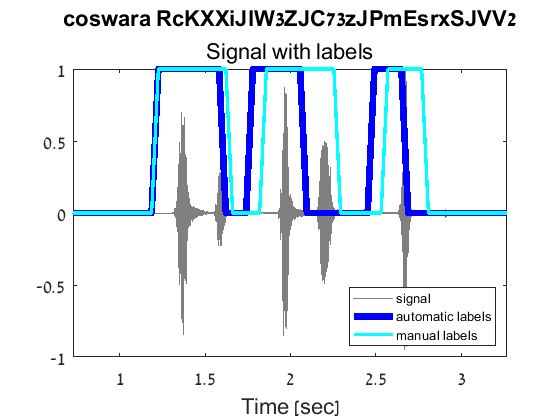

    19



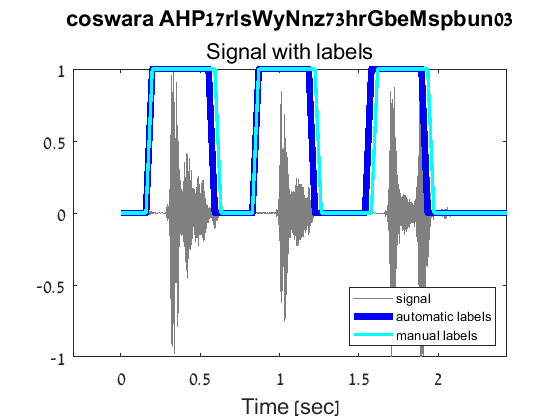

    20



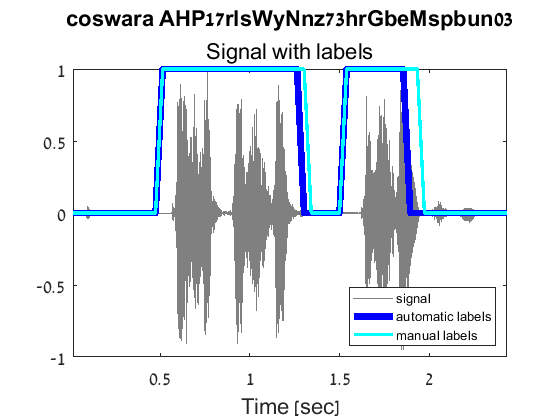

    21



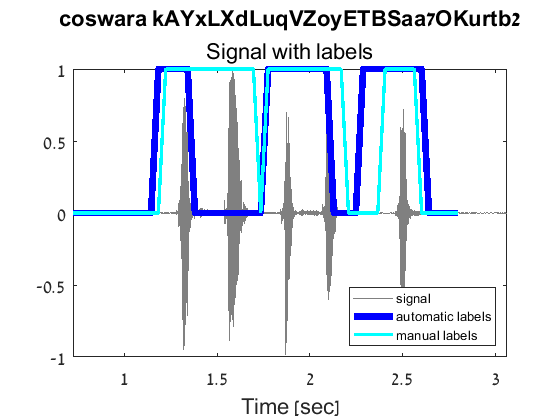

    22



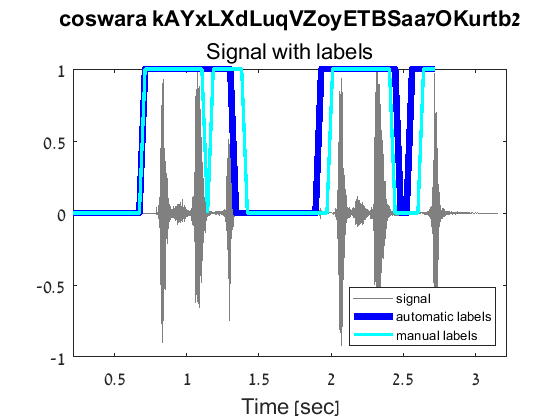

    23



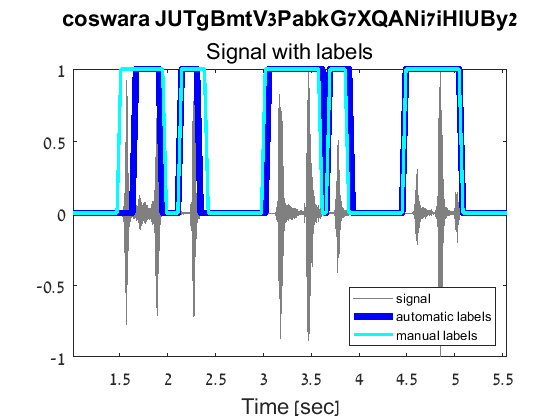

    24



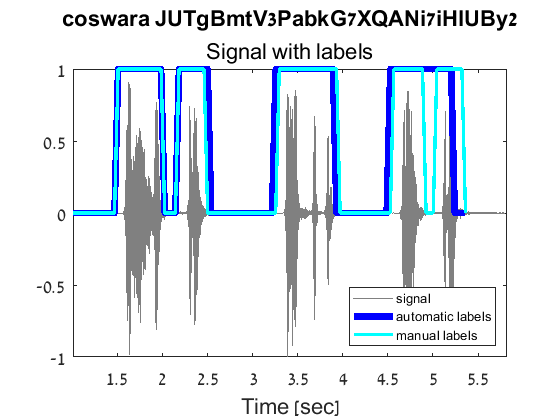

    25



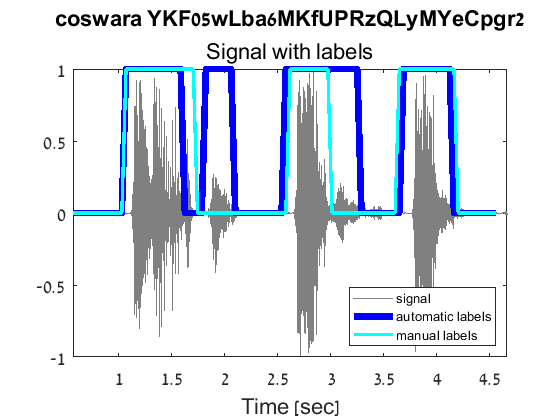

    26



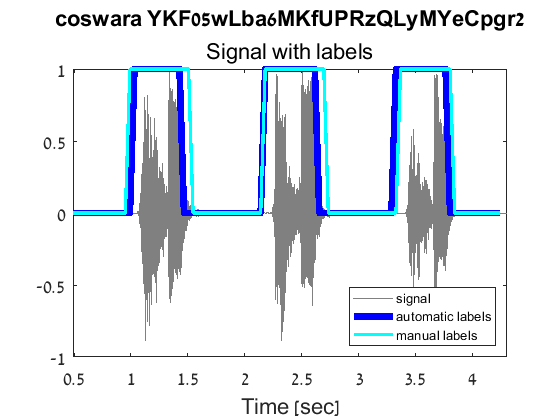

    27



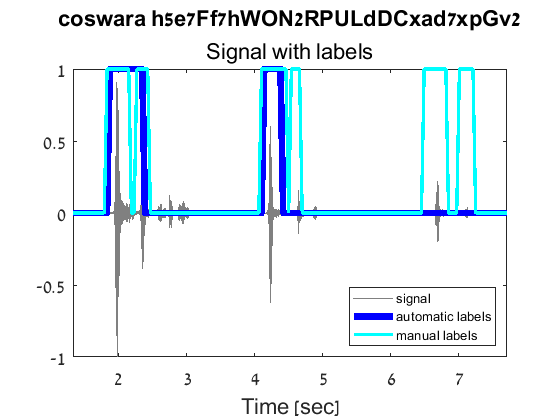

    28



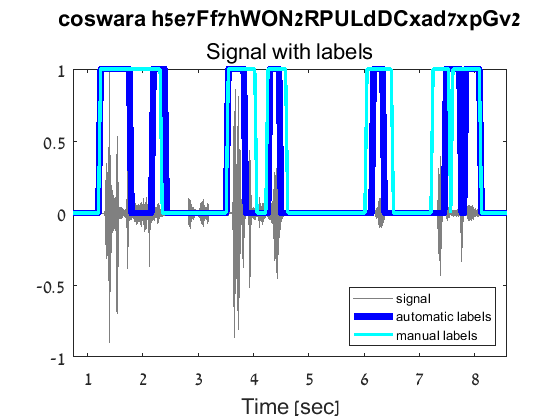

    29



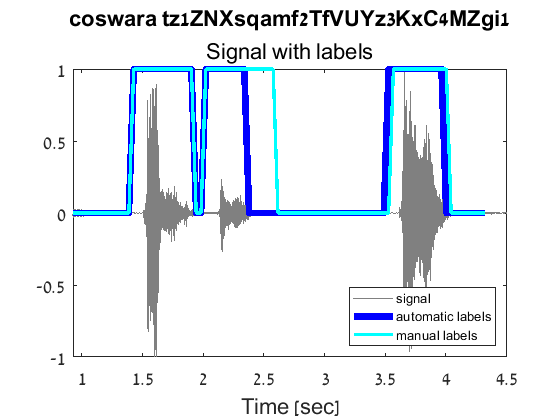

    30



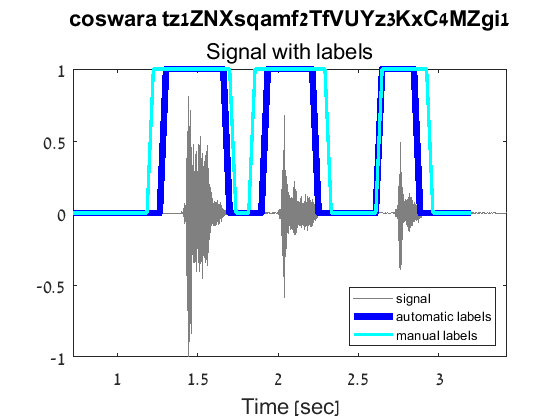

    31



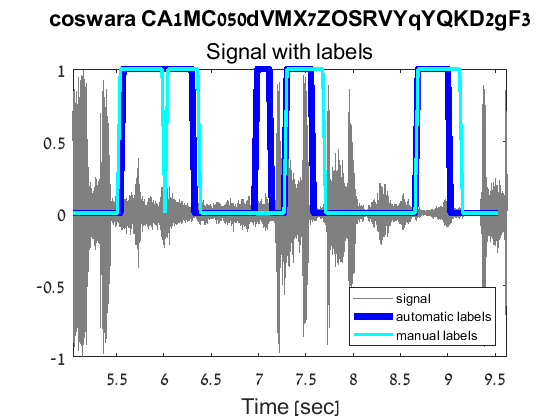

    32



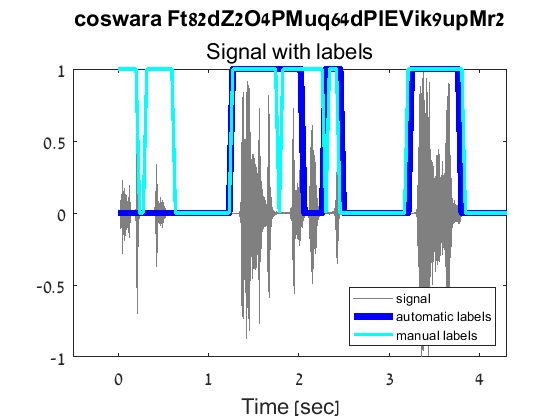

    33



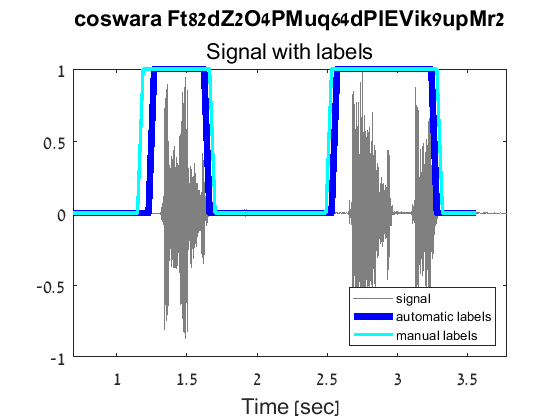

    34



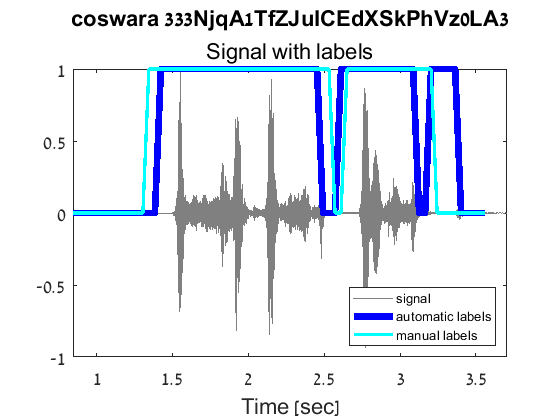

    35



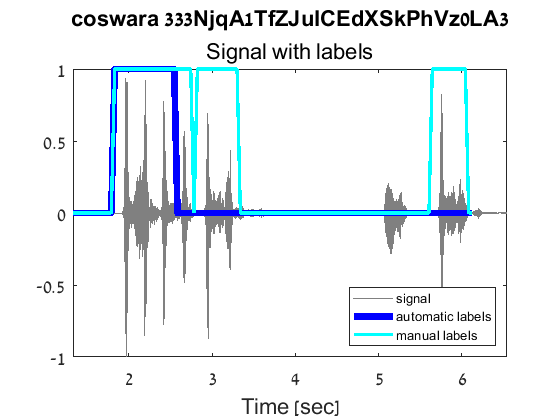

    36



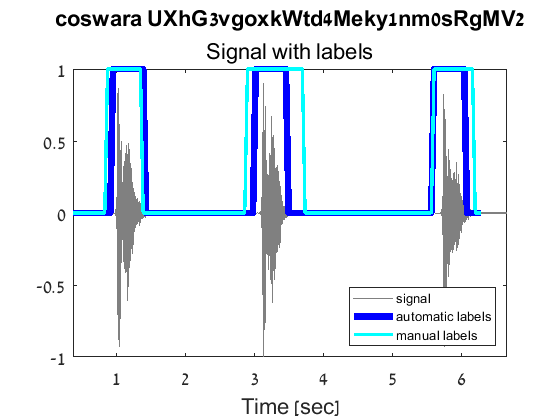

    37



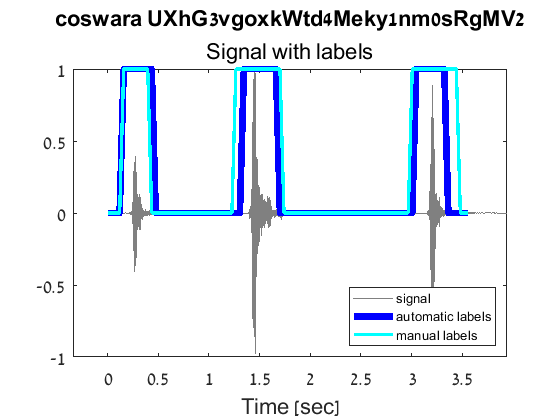

    38



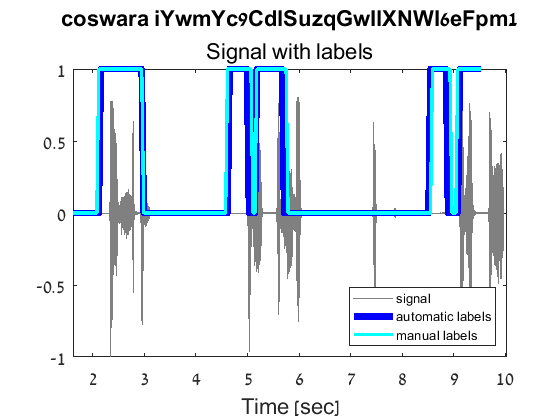

    39



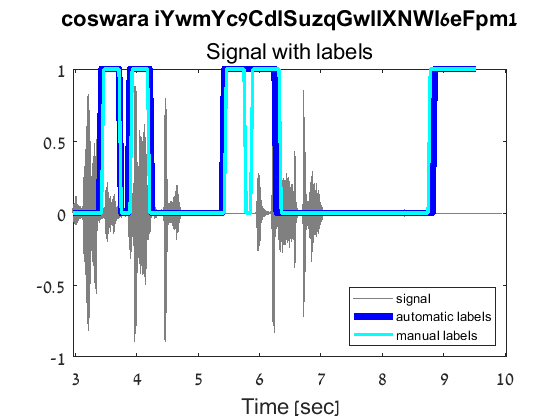

    40



% ads from spesific folder
folderName = "\\zigel-server-5\Corona\DataBase\coughvid\audioDataFolderVer2\positive";
newAds = loadNewAds(folderName);

adsPredict = adsTest; % choose which dataset to use
addTrueLbls = "yes"; % choose if to add true labels
coughSegYamnetRslts = predictOnNewAds(netSegCoughYamnet, adsPredict, winInfo, rocThreshold, addTrueLbls);